clear all

t = (0:1:4)'

t =      0
     1
     2
     3
     4



pp=bspline(t) 

pp = struct with fields:
      form: 'pp'
    breaks: [0 1 2 3 4]
     coefs: [4×4 double]
    pieces: 4
     order: 4
       dim: 1


flipud(pp.coefs)

ans =    -0.1667    0.5000   -0.5000    0.1667
    0.5000   -1.0000         0    0.6667
   -0.5000    0.5000    0.5000    0.1667
    0.1667         0         0         0


[1 -2 1; -2 2 1; 1 0 0]

ans =      1    -2     1
    -2     2     1
     1     0     0



timesteps = 20

timesteps = 20


t=linspace(0,1,timesteps+1)'

t =          0
    0.0500
    0.1000
    0.1500
    0.2000
    0.2500
    0.3000
    0.3500
    0.4000
    0.4500


t(end)=[];

M = 0.5*[1 -2 1; -2 2 1; 1 0 0]

M =     0.5000   -1.0000    0.5000
   -1.0000    1.0000    0.5000
    0.5000         0         0



knots = 10

knots = 10

index= [];

output1 = sin(exp(t)+sin(10*t).^2+3*cos(3*t)+0.3*rand(timesteps,1));
output2= cos(5*t)+0.4*rand(timesteps,1)

output2 =     1.0606
    1.0182
    0.9551
    0.8347
    0.8316
    0.4047
    0.3096
   -0.1086
   -0.1861
   -0.4446



output_curve = outproduct(output1,output2);

Y = output_curve(:)

Y =    -0.9059
   -0.9660
   -1.0435
   -1.0270
   -1.0606
   -0.7778
   -0.3338
    0.0359
   -0.0706
   -0.0902


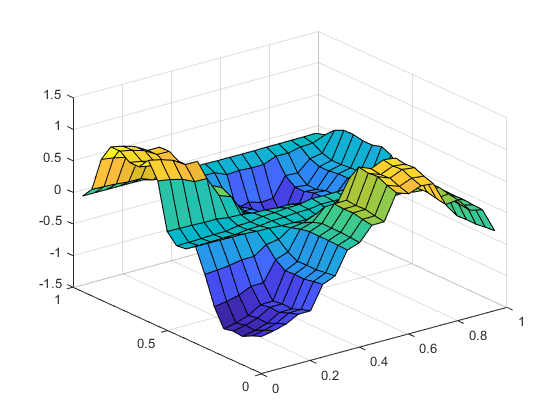





% output_curve(1:80,1:80)=0
surf(t,t,output_curve);

% 
% plot(output1)
% plot(output2)

N=zeros(length(t),knots+2);
B=[]


B =

     []



C=[]


C =

     []




for i=1:length(t)
   index(i)= floor((t(i)*knots+(10*knots*eps)))+1;
    Ntemp = (mod(t(i),1/knots)*knots).^linspace(2,0,3)*M';
%     Ntemp = (t(i)-(index(i)-1)/timesteps/knots).^linspace(2,0,3)*M';
    N(i,index(i):index(i)+2) = Ntemp;
end

for ii= 1:timesteps
    for jj=1:timesteps

N_multi = outproduct(N(ii,:),N(jj,:));

N_T{(ii-1)*timesteps+jj}= [N(ii,:);N(jj,:)];

   B(jj,:)=N_multi(:)';
    end
    C = [C ; B];
end


% -------------------------------------
tic
Theta=zeros((knots+2)^2,1)

Theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Pcov =eye((knots+2)^2)*10000

Pcov =        10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0       10000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0        



for kk=1:400
    
Phi = C(kk,:);

Pcov = Pcov - (Pcov * Phi'*Phi * Pcov)/(1+Phi*Pcov*Phi');

epsilo(kk) = Y(kk) - Phi * Theta;

K = Pcov*Phi';
Theta = Theta + K *epsilo(kk);

end

toc

Elapsed time is 0.102045 seconds.


% -----------------------------------
tic
P=pinv(C)*output_curve(:);
toc

Elapsed time is 0.016494 seconds.



tol=10^-3

tol = 1.0000e-03

lambda=0.95

lambda = 0.9500


d=2

d = 2

n=(knots+2)

n = 12

l=1

l = 1


sigmas= [100000]

sigmas = 100000


PcovT=initP(sigmas,n,d)

PcovT = struct with fields:
       n: [2×5 double]
    core: {[12×12 double]  [12×12 double]}


PcovT.n

ans =      1    12    12     1     1
     1    12    12     1     1


ttcontractkim(PcovT)

ans =       100000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0
           0      100000           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0           0         


XT=initm(l,n,d)

XT = struct with fields:
       n: [2×4 double]
    core: {[0 0 0 0 0 0 0 0 0 0 0 0]  [0 0 0 0 0 0 0 0 0 0 0 0]}


XT.core

ans = 1×2 cell array
    {1×12 double}    {1×12 double}


XT.n

ans =      1    12     1     1
     1    12     1     1


% ttcontractkim(XT)
lambda=0.5

lambda = 0.5000

% ------------------------------------
for epochs=1:2
    
indexez= randperm(400);    
    
    if epochs>1
      lambda=1
%     lambda=0.9+epochs/50
    end
    
for kk=1:400

Phi = N_T{indexez(kk)};
f = contractCPC(XT,Phi);

epsil(kk) = Y(indexez(kk)) - f;

Pc = contractPC(PcovT,Phi,0);
% ttcontractkim(Pc);

cP = contractPC(PcovT,Phi,1);
% ttcontractkim(cP);

cPc = contractCPC(Pc,Phi);

c=squareTN(Pc,cP);
% ttcontractkim(c);

for j=1:size(c.n,1)
c.core{j} = reshape(c.core{j},c.n(j,:));
end

c.core{1} = c.core{1}*(-1/(lambda+cPc));
% ttcontractkim(c);

PcovT = addTN(c,PcovT);

if mod(kk,1)==0
PcovT = roundTN(PcovT,tol);
end

PcovT = reshapeP(PcovT);
PcovT.core{end}= PcovT.core{end}*lambda;

% ttcontractkim(PcovT)

K = contractPC(PcovT,Phi,0);

K.core{1}= K.core{1}*epsil(kk);
% ttcontractkim(K);

XT = addTN(XT,K);

if mod(kk,1)==0
XT = roundTN(XT,tol);
end

% 

end
end

lambda = 1

test =ttcontractkim(XT);

y=C*test;
y=C*P;
y=C*Theta;
y=C*test;

norm(test-P)

ans = 13.7701

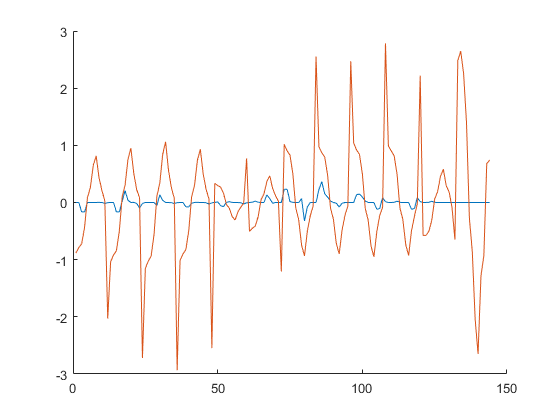


figure;
hold on
plot(test)
plot(Theta)
% plot(P)
hold off

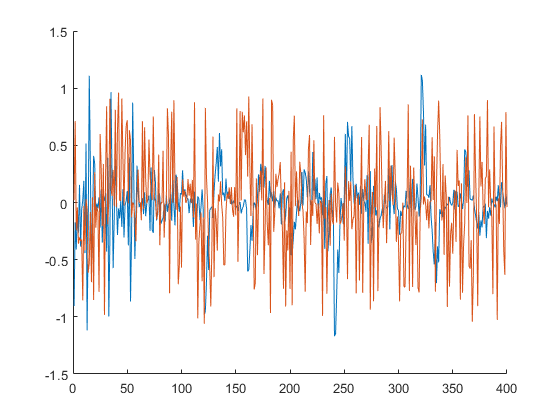


figure;
hold on
plot(epsilo)
plot(epsil)
hold off

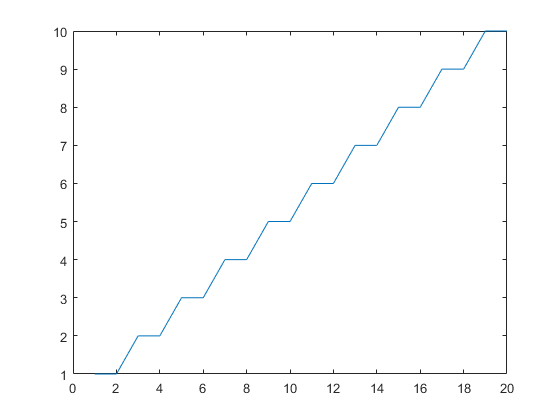


plot(index)

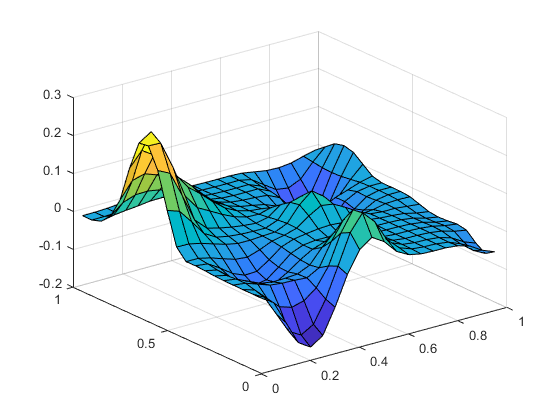

surf(t,t,reshape(y,[timesteps timesteps]))

surf(t,t,output_curve)

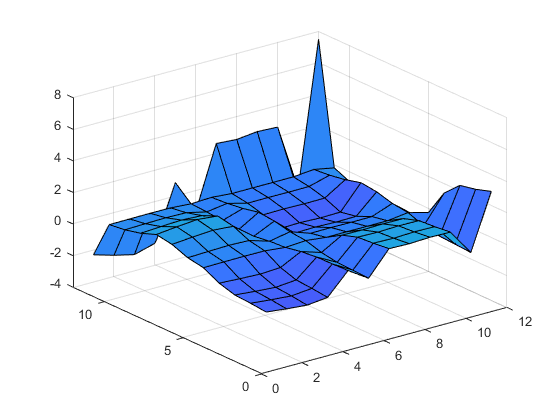


surf(1:knots+2,1:knots+2,reshape(P,[knots+2 knots+2]))


norm(reshape(y,[timesteps timesteps])-output_curve)

ans = 8.9044

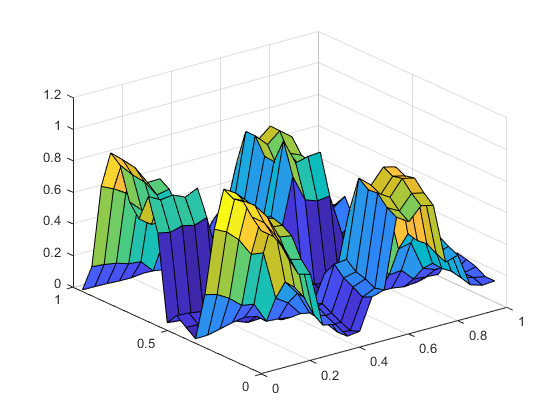


 surf(t,t,abs(reshape(y,[timesteps timesteps])-output_curve))


[coeff,score,latent] = pca(reshape(P,[knots+2 knots+2]))

coeff =    -0.2128    0.5608   -0.1895    0.4277    0.2760   -0.2397   -0.1712   -0.1055    0.2729    0.2719   -0.2504
   -0.2482   -0.2362    0.5665   -0.1937    0.2295    0.3059   -0.1011   -0.3644    0.1147    0.2910   -0.2395
   -0.2768    0.3817   -0.0413   -0.1968    0.3859    0.5539    0.2245    0.2835    0.1157   -0.1334    0.3396
   -0.2432    0.0284    0.4113    0.1292   -0.4639   -0.1003    0.0383    0.5257    0.2978    0.3585    0.1373
    0.0802   -0.1006    0.1108    0.1222    0.0320   -0.2264    0.3810   -0.4289    0.6028   -0.2104    0.4076
   -0.1213    0.1885   -0.1087   -0.0534   -0.2805    0.1956   -0.4330   -0.4755   -0.0847    0.2597    0.3757
    0.2439   -0.2348    0.1189   -0.0081    0.6288   -0.2372   -0.1935    0.2016    0.0538    0.2681    0.0945
    0.2349    0.0017   -0.2044    0.0832   -0.0466    0.1990    0.6452   -0.1294   -0.1547    0.6147   -0.1017
    0.2483   -0.3492   -0.1623    0.5910   -0.0094    0.5254   -0.2625    0.1221    0.2079   -0.0025    

score =     3.1432    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000
    2.6765   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    2.3666    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000
    1.0103    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000
   -1.4386    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000
   -2.2544   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -4.0721   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000
   -4.8566   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000
   -3.0810   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -

latent =    16.5320
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


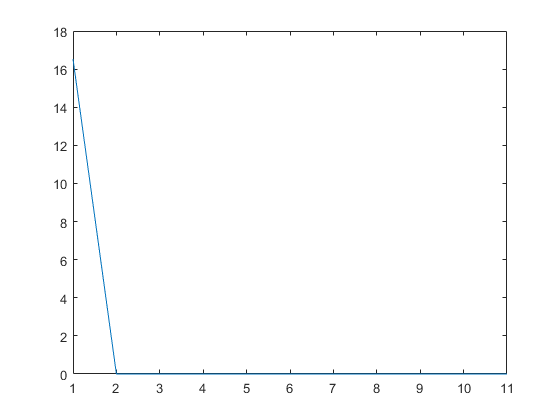


plot(latent)